Extracted 52 features from 635 samples
Training set: 240 Non-Seizure samples, 205 Seizure samples
Validation set: 51 Non-Seizure samples, 44 Seizure samples
Test set: 55 Non-Seizure samples, 40 Seizure samples
Features standardized using training data statistics
Class ratio (Non-Seizure:Seizure): 1.1707:1
Cost matrix:
         0    1.0000
    1.1707         0

Starting hyperparameter optimization...
This may take some time...
|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.22472 |     0.15278 |     0.22472 |     0.22472 |       170.65 |       116.49 |
|    2 | Accept |     0.46067 |     0.10874 |     

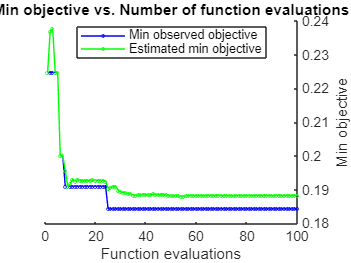

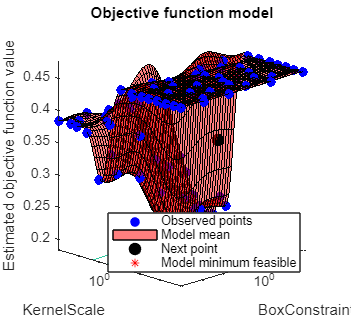


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 75.8889 seconds
Total objective function evaluation time: 10.2196

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       983.38          38.917   

Observed objective function value = 0.18427
Estimated objective function value = 0.18824
Function evaluation time = 0.17959

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       983.38          38.917   

Estimated objective function value = 0.18824
Estimated function evaluation time = 0.14701

Best hyperparameters:
BoxConstraint: 983.3781
KernelScale: 38.9172
SVM model training completed
Optimal decision thresho

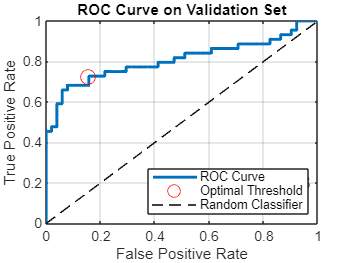

Test Accuracy: 81.05%
Sensitivity (Seizure Recall): 87.50%
Specificity: 76.36%
Precision: 72.92%
F1 Score: 79.55


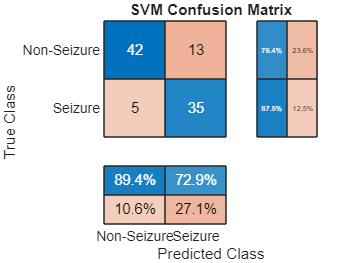

Calculating feature importance via permutation...
Progress: ..........


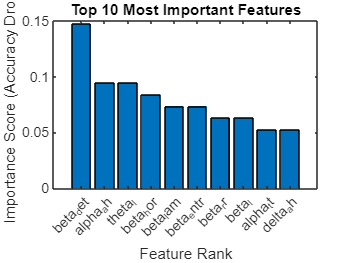

Top 5 most important features:
1. beta_det: 0.1474
2. alpha_ah: 0.0947
3. theta_l: 0.0947
4. beta_hor: 0.0842
5. beta_lam: 0.0737


main_seizure_detection(outputEntries);

function main_seizure_detection(entries)
    % Set random seed for reproducibility
    rng(42);
    
    % Extract and prepare data
    [X, labels] = extractFeatures(entries);
    
    % Split data into train, validation, and test sets
    [XTrain, YTrain, XVal, YVal, XTest, YTest] = splitData(X, labels);
    
    % Standardize features
    [XTrain, XVal, XTest] = standardizeFeatures(XTrain, XVal, XTest);
    
    % Train model with class weights
    svmModel = trainWeightedSVM(XTrain, YTrain);
    
    % Optimize decision threshold using validation set
    [optThreshold, fpr, tpr, thresholds] = optimizeThreshold(svmModel, XVal, YVal);
    
    % Plot ROC curve
    plotROC(fpr, tpr, thresholds, optThreshold);
    
    % Evaluate on test set
    evaluateModel(svmModel, XTest, YTest, optThreshold);
    
    % Analyze feature importance
    analyzeFeatureImportance(svmModel, XTest, YTest, entries);
end

%% Extract features from the data structure
function [X, labels] = extractFeatures(entries)
    % Initialize
    numEntries = length(entries);
    featureList = fieldnames(entries{1}.alphaRQA);  % Assumes all RQA structs have same fields
    numFeaturesPerBand = numel(featureList);
    numBands = 4;  % alpha, beta, delta, theta
    totalFeatures = numFeaturesPerBand * numBands;
    
    % Allocate space
    X = zeros(numEntries, totalFeatures);
    labels = zeros(numEntries, 1);
    
    % Extract features
    for i = 1:numEntries
        featVec = [];
        for band = {'alphaRQA', 'betaRQA', 'deltaRQA', 'thetaRQA'}
            bandStruct = entries{i}.(band{1});
            bandFeatures = cellfun(@(f) bandStruct.(f), featureList)';  % transpose to row
            featVec = [featVec, bandFeatures];  % 1x13 per band
        end
        X(i, :) = featVec;  % now 1x52
        labels(i) = entries{i}.seizure;
    end
    
    % Confirm numeric matrix
    assert(isnumeric(X), 'Feature matrix X is not numeric!');
    
    % Convert labels to categorical
    labels = categorical(labels, [0 1], {'Non-Seizure', 'Seizure'});
    
    disp(['Extracted ' num2str(totalFeatures) ' features from ' num2str(numEntries) ' samples']);
end

%% Split data into train, validation, and test sets
function [XTrain, YTrain, XVal, YVal, XTest, YTest] = splitData(X, labels)
    % Shuffle and split into train (70%), val (15%), test (15%)
    numSamples = size(X, 1);
    idx = randperm(numSamples);
    trainIdx = idx(1:round(0.7 * numSamples));
    valIdx   = idx(round(0.7 * numSamples) + 1 : round(0.85 * numSamples));
    testIdx  = idx(round(0.85 * numSamples) + 1 : end);

    XTrain = X(trainIdx, :);
    YTrain = labels(trainIdx);
    XVal = X(valIdx, :);
    YVal = labels(valIdx);
    XTest = X(testIdx, :);
    YTest = labels(testIdx);
    
    % Display class distribution in training set
    numNonSeizure = sum(YTrain == 'Non-Seizure');
    numSeizure = sum(YTrain == 'Seizure');
    disp(['Training set: ' num2str(numNonSeizure) ' Non-Seizure samples, ' ...
          num2str(numSeizure) ' Seizure samples']);
    
    % Display class distribution in validation set
    disp(['Validation set: ' num2str(sum(YVal == 'Non-Seizure')) ' Non-Seizure samples, ' ...
          num2str(sum(YVal == 'Seizure')) ' Seizure samples']);
    
    % Display class distribution in test set
    disp(['Test set: ' num2str(sum(YTest == 'Non-Seizure')) ' Non-Seizure samples, ' ...
          num2str(sum(YTest == 'Seizure')) ' Seizure samples']);
end

%% Standardize features
function [XTrain, XVal, XTest] = standardizeFeatures(XTrain, XVal, XTest)
    % Standardize features correctly using only training data statistics
    [XTrain, mu, sigma] = zscore(XTrain);
    
    % Apply same transformation to validation and test sets
    XVal = (XVal - mu) ./ sigma;
    XTest = (XTest - mu) ./ sigma;
    
    % Check for any potential NaN or Inf values after standardization
    XTrain(isnan(XTrain)) = 0;
    XVal(isnan(XVal)) = 0;
    XTest(isnan(XTest)) = 0;
    
    disp('Features standardized using training data statistics');
end

%% Train SVM model with class weights
function svmModel = trainWeightedSVM(XTrain, YTrain)
    % Count samples in each class
    numNonSeizure = sum(YTrain == 'Non-Seizure');
    numSeizure = sum(YTrain == 'Seizure');
    
    % Calculate class ratio and cost matrix
    classRatio = numNonSeizure / numSeizure;
    disp(['Class ratio (Non-Seizure:Seizure): ' num2str(classRatio) ':1']);
    
    % Define cost matrix:
    % [0,W1; W2,0] where:
    % - W1 is cost of misclassifying Non-Seizure as Seizure
    % - W2 is cost of misclassifying Seizure as Non-Seizure (higher)
    costMatrix = [0, 1; classRatio, 0];
    disp('Cost matrix:');
    disp(costMatrix);
    
    % Train SVM with RBF kernel and class weights
    svmModel = fitcsvm(XTrain, YTrain, ...
        'KernelFunction', 'rbf', ...
        'KernelScale', 'auto', ... % Automatically determine best kernel scale
        'Standardize', false, ... % We've already standardized
        'ClassNames', {'Non-Seizure', 'Seizure'}, ...
        'Cost', costMatrix);
    
    % Optional: Try hyperparameter optimization
    try
        % Hyperparameter optimization using Bayesian optimization
        cvp = cvpartition(YTrain, 'KFold', 5);
        
        % Set up hyperparameter optimization options
        opts = struct(...
            'Optimizer', 'bayesopt', ...
            'MaxObjectiveEvaluations', 30, ...
            'AcquisitionFunctionName', 'expected-improvement-plus', ...
            'ShowPlots', true, ...
            'Verbose', 1, ...
            'CVPartition', cvp);
        
        disp('Starting hyperparameter optimization...');
        disp('This may take some time...');
        
        % Perform hyperparameter optimization
        svmModel = fitcsvm(XTrain, YTrain, ...
            'KernelFunction', 'rbf', ...
            'Standardize', false, ...
            'ClassNames', {'Non-Seizure', 'Seizure'}, ...
            'Cost', costMatrix, ...
            'OptimizeHyperparameters', {'BoxConstraint', 'KernelScale'}, ...
            'HyperparameterOptimizationOptions', opts);
        
        % Get best hyperparameters
        bestHPs = svmModel.HyperparameterOptimizationResults.XAtMinObjective;
        
        disp('Best hyperparameters:');
        disp(['BoxConstraint: ' num2str(bestHPs.BoxConstraint)]);
        disp(['KernelScale: ' num2str(bestHPs.KernelScale)]);
    catch e
        disp('Hyperparameter optimization failed. Using default model instead.');
        disp(['Error: ' e.message]);
    end
    
    disp('SVM model training completed');
end

%% Optimize decision threshold using validation set
function [optThreshold, fpr, tpr, thresholds] = optimizeThreshold(svmModel, XVal, YVal)
    % Evaluate on validation set and adjust probability thresholds
    [~, YValScores] = predict(svmModel, XVal);
    
    % Create ROC curve on validation set
    [fpr, tpr, thresholds] = perfcurve(YVal, YValScores(:,2), 'Seizure');
    
    % Find optimal threshold using validation set
    % This optimizes for balanced performance (closest to perfect corner)
    distToIdeal = sqrt((fpr - 0).^2 + (tpr - 1).^2); % Distance to perfect corner (0,1)
    [~, idxOptThresh] = min(distToIdeal);
    optThreshold = thresholds(idxOptThresh);
    
    disp(['Optimal decision threshold: ' num2str(optThreshold)]);
    
    % Calculate validation metrics at optimal threshold
    YValPredOpt = categorical(YValScores(:,2) >= optThreshold, [0 1], {'Non-Seizure', 'Seizure'});
    valAccuracy = sum(YValPredOpt == YVal) / numel(YVal);
    
    % Calculate detailed metrics for validation set
    TP = sum(YValPredOpt == 'Seizure' & YVal == 'Seizure');
    FP = sum(YValPredOpt == 'Seizure' & YVal == 'Non-Seizure');
    TN = sum(YValPredOpt == 'Non-Seizure' & YVal == 'Non-Seizure');
    FN = sum(YValPredOpt == 'Non-Seizure' & YVal == 'Seizure');
    
    valSensitivity = TP / (TP + FN) * 100;
    valSpecificity = TN / (TN + FP) * 100;
    
    disp(['Validation Accuracy: ' num2str(valAccuracy * 100, '%.2f') '%']);
    disp(['Validation Sensitivity: ' num2str(valSensitivity, '%.2f') '%']);
    disp(['Validation Specificity: ' num2str(valSpecificity, '%.2f') '%']);
end

%% Plot ROC curve
function plotROC(fpr, tpr, thresholds, optThreshold)
    % Find index of optimal threshold
    [~, idxOptThresh] = min(abs(thresholds - optThreshold));
    
    % Plot ROC curve
    figure;
    plot(fpr, tpr, 'LineWidth', 2);
    hold on;
    plot(fpr(idxOptThresh), tpr(idxOptThresh), 'ro', 'MarkerSize', 10);
    plot([0 1], [0 1], 'k--');
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    title('ROC Curve on Validation Set');
    legend('ROC Curve', 'Optimal Threshold', 'Random Classifier', 'Location', 'southeast');
    grid on;
    
    % Add AUC value to the plot
    AUC = trapz(fpr, tpr);
    text(0.6, 0.2, ['AUC = ' num2str(AUC, '%.3f')], 'FontSize', 12);
end

%% Evaluate model on test set
function evaluateModel(svmModel, XTest, YTest, optThreshold)
    % Predict on test set using optimal threshold
    [~, YTestScores] = predict(svmModel, XTest);
    YTestPred = categorical(YTestScores(:,2) >= optThreshold, [0 1], {'Non-Seizure', 'Seizure'});
    
    % Evaluate accuracy
    testAccuracy = sum(YTestPred == YTest) / numel(YTest);
    disp(['Test Accuracy: ' num2str(testAccuracy * 100, '%.2f') '%']);
    
    % Calculate detailed metrics
    TP = sum(YTestPred == 'Seizure' & YTest == 'Seizure');
    FP = sum(YTestPred == 'Seizure' & YTest == 'Non-Seizure');
    TN = sum(YTestPred == 'Non-Seizure' & YTest == 'Non-Seizure');
    FN = sum(YTestPred == 'Non-Seizure' & YTest == 'Seizure');
    
    sensitivity = TP / (TP + FN) * 100; % Recall for seizure class
    specificity = TN / (TN + FP) * 100;
    precision = TP / (TP + FP) * 100;
    f1score = 2 * (precision * sensitivity) / (precision + sensitivity);
    
    disp(['Sensitivity (Seizure Recall): ' num2str(sensitivity, '%.2f') '%']);
    disp(['Specificity: ' num2str(specificity, '%.2f') '%']);
    disp(['Precision: ' num2str(precision, '%.2f') '%']);
    disp(['F1 Score: ' num2str(f1score, '%.2f')]);
    
    % Show confusion matrix
    figure;
    cm = confusionchart(YTest, YTestPred);
    cm.Title = 'SVM Confusion Matrix';
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
end

%% Analyze feature importance
function analyzeFeatureImportance(svmModel, XTest, YTest, entries)
    try
        % Get feature list for naming
        featureList = fieldnames(entries{1}.alphaRQA);
        
        % Create a wrapper function to evaluate model performance
        scoreModel = @(X, Y) sum(predict(svmModel, X) == Y) / numel(Y);
        
        % Initialize feature importance vector
        totalFeatures = size(XTest, 2);
        featureImportance = zeros(totalFeatures, 1);
        
        % Calculate baseline performance
        baselineScore = scoreModel(XTest, YTest);
        
        disp('Calculating feature importance via permutation...');
        
        % Progress indicator setup
        fprintf('Progress: ');
        progressMarks = 10;
        progressStep = totalFeatures / progressMarks;
        
        % Evaluate each feature's importance by permutation
        for i = 1:totalFeatures
            % Create a copy of test data with the i-th feature permuted
            XTestPerm = XTest;
            XTestPerm(:, i) = XTestPerm(randperm(size(XTestPerm, 1)), i);
            
            % Calculate performance drop
            permScore = scoreModel(XTestPerm, YTest);
            featureImportance(i) = baselineScore - permScore;
            
            % Show progress
            if mod(i, round(progressStep)) == 0
                fprintf('.');
            end
        end
        fprintf('\n');
        
        % Create feature names by combining band and RQA feature
        bands = {'alpha', 'beta', 'delta', 'theta'};
        allFeatureNames = {};
        featureIdx = 1;
        
        for b = 1:length(bands)
            for f = 1:length(featureList)
                allFeatureNames{featureIdx} = [bands{b} '_' featureList{f}];
                featureIdx = featureIdx + 1;
            end
        end
        
        % Get top 10 features
        [sortedImportance, sortedIndices] = sort(featureImportance, 'descend');
        topFeatures = sortedIndices(1:min(10, length(sortedIndices)));
        
        % Plot top features
        figure;
        bar(sortedImportance(1:10));
        xlabel('Feature Rank');
        ylabel('Importance Score (Accuracy Drop)');
        title('Top 10 Most Important Features');
        xticks(1:10);
        xticklabels(allFeatureNames(sortedIndices(1:10)));
        xtickangle(45);
        
        % Display top 5 features with their importance scores
        disp('Top 5 most important features:');
        for i = 1:5
            disp([num2str(i) '. ' allFeatureNames{sortedIndices(i)} ': ' ...
                num2str(sortedImportance(i), '%.4f')]);
        end
        
    catch e
        disp('Feature importance analysis failed. This may require additional toolboxes.');
        disp(['Error: ' e.message]);
    end
end